clear;close;clf

## Problem 1

% part a
load('SIO_PIER_1916_201905.mat');
t = datetime(t,'ConvertFrom','datenum');

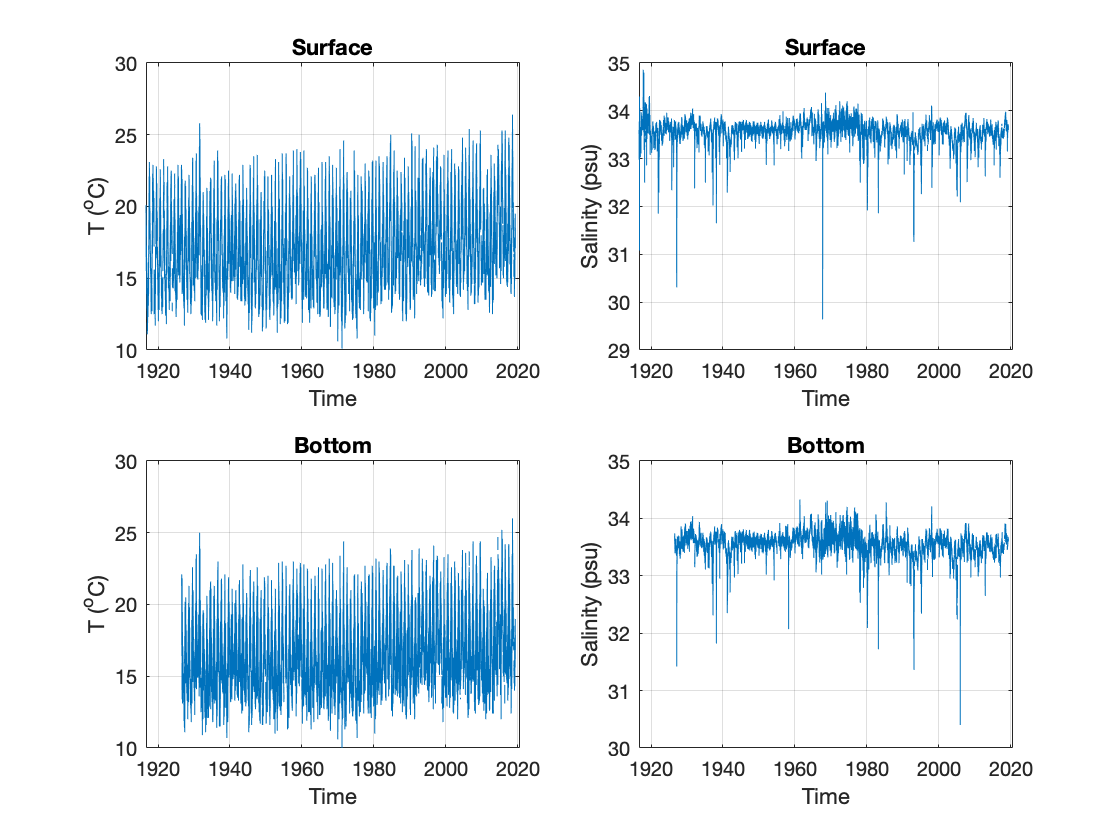

clf
subplot(2,2,1);plot(t,Ts)
subplot(2,2,2);plot(t,Ss)
subplot(2,2,3);plot(t,Tb)
subplot(2,2,4);plot(t,Sb)


for i=1:4;subplot(2,2,i)
    grid;xlabel('Time');xlim([t(1),t(end)+365]) % all same dates
end
for i=1:2;subplot(2,2,i);title('Surface');end
for i=3:4;subplot(2,2,i);title('Bottom');end
for i=[1,3];subplot(2,2,i)
    ylabel('T (^oC)')
end
for i=[2,4];subplot(2,2,i)
    ylabel('Salinity (psu)')
end

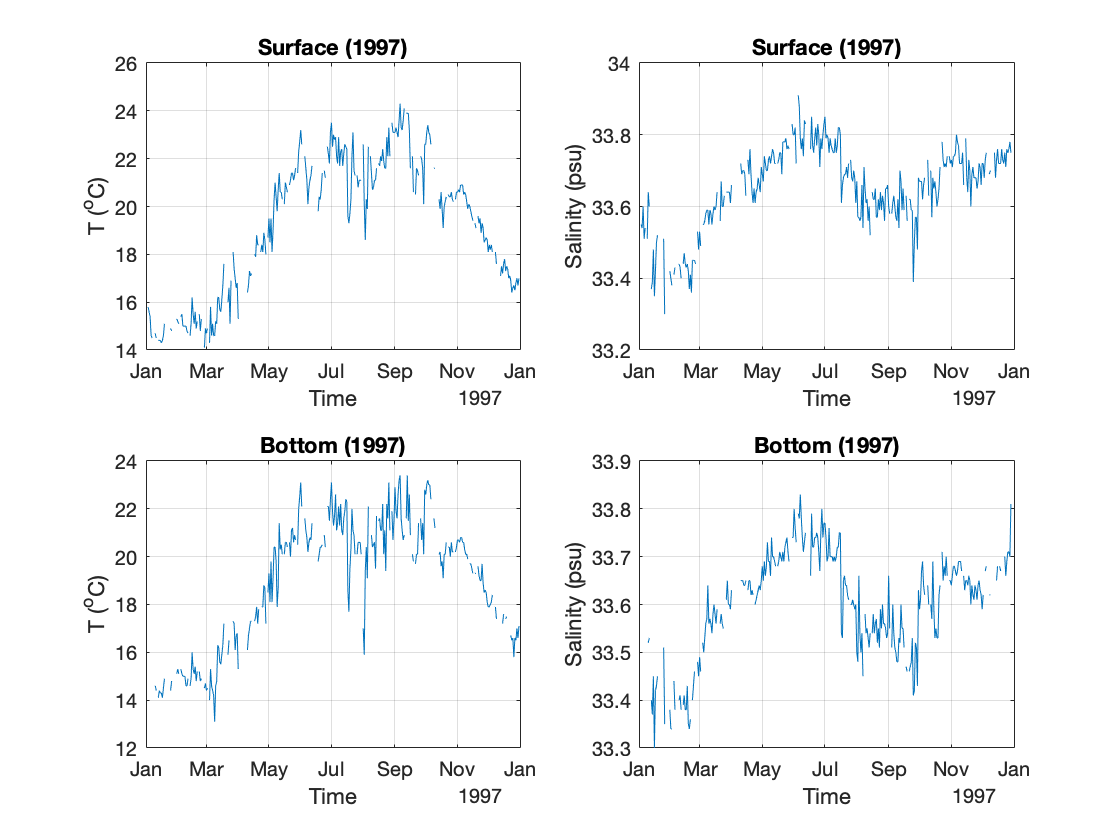

% part b
% look at a year -- > choose 1997-1998
clf
g = find((year(datetime(t,'ConvertFrom','datenum'))==1997));

subplot(2,2,1);plot(t(g),Ts(g))
subplot(2,2,2);plot(t(g),Ss(g))
subplot(2,2,3);plot(t(g),Tb(g))
subplot(2,2,4);plot(t(g),Sb(g))

for i=1:4;subplot(2,2,i);grid;xlabel('Time');end
for i=1:2;subplot(2,2,i);title('Surface (1997)');end
for i=3:4;subplot(2,2,i);title('Bottom (1997)');end
for i=[1,3];subplot(2,2,i)
    ylabel('T (^oC)')
end
for i=[2,4];subplot(2,2,i)
    ylabel('Salinity (psu)')
end

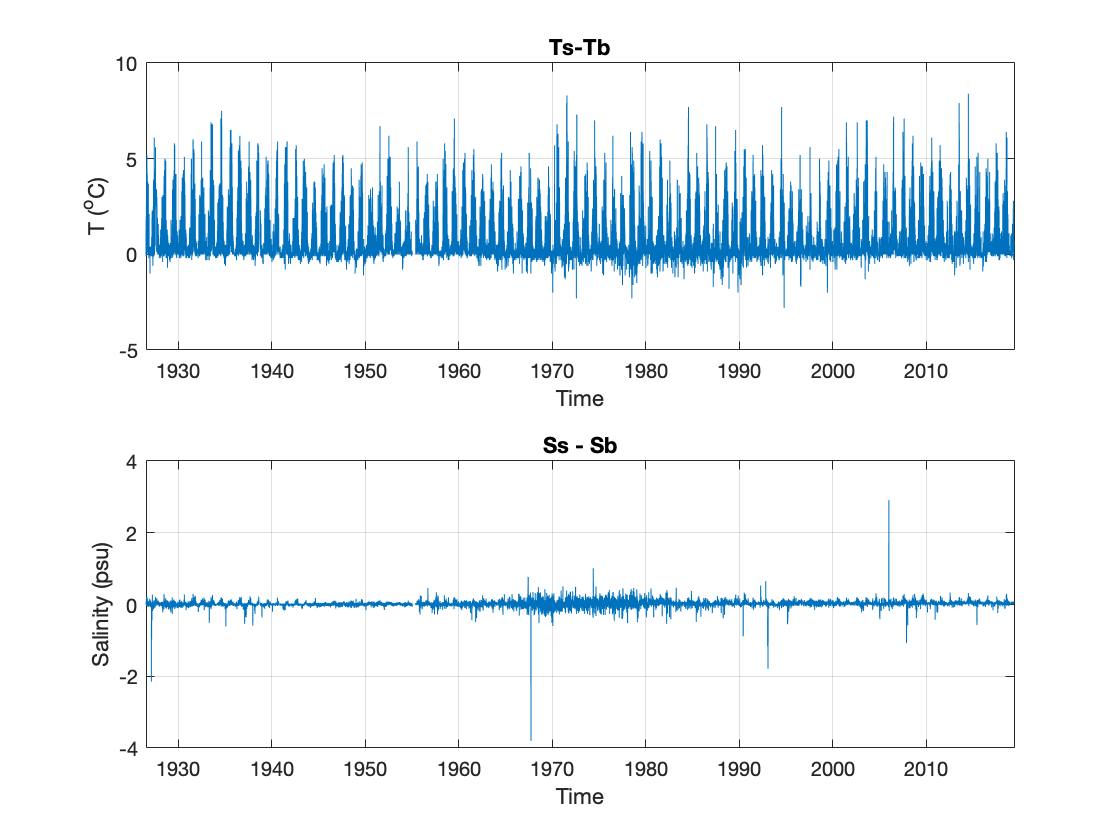

% part c
% plot diff between surface and bottom data over the year
clf
subplot(2,1,1);plot(t,Ts-Tb);grid;title('Ts-Tb');ylabel('T (^oC)');xlabel('Time');
subplot(2,1,2);plot(t,Ss-Sb);grid;title('Ss - Sb');ylabel('Salinity (psu)');xlabel('Time');

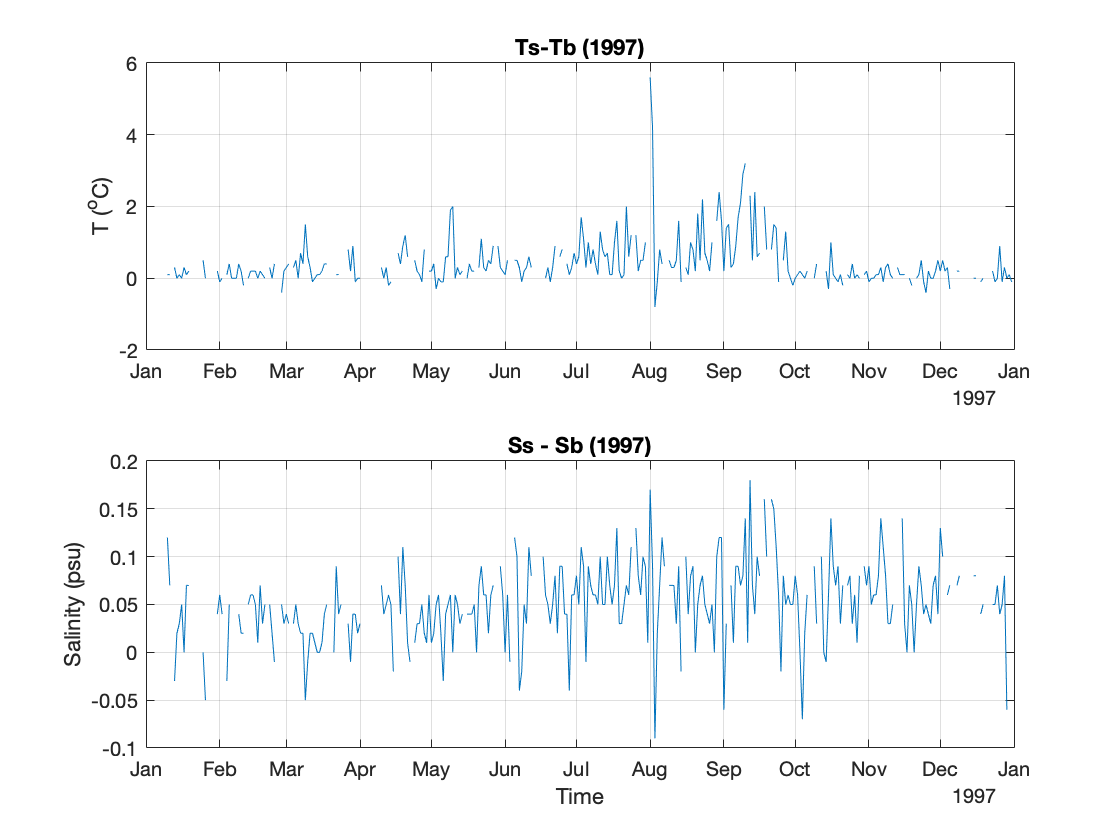

figure(2)
subplot(2,1,1);plot(t(g),Ts(g)-Tb(g));grid;title('Ts-Tb (1997)');ylabel('T (^oC)')
subplot(2,1,2);plot(t(g),Ss(g)-Sb(g));grid;title('Ss - Sb (1997)');ylabel('Salinity (psu)')
xlabel('Time')

% describe any notable features

When plotting the entire 100-year series there are a few drops in salinity (e.g., ~1969), probability indicative of massive precipitation events. Using the same time limits when plotting the entire series, we see that bottom salinity and temperature data is not collected until around 1926. Surface and bottom temperatures see an overall increase after 1980 or so. We see a huge spike between temperature difference/ salinity difference around August 1997 when the most intense ENSO event occured, meaning that suface temperature/salinity  was far greater than bottom temperature/salinity at the time of ENSO. 

## Problem 2

clf
plot(t,Ts,'HandleVisibility','off');
hold;grid;xlim([t(1)-365,t(end)+365])

Current plot held


[m,i] = max(Ts(:));
scatter(t(i),Ts(i),'red','marker','o')
disp(['The max temperature value is ',num2str(m),'C.'])

The max temperature value is 26.4C.


[m,i] = min(Ts(:));
scatter(t(i),Ts(i),'c','marker','o')
disp(['The min temperature value is ',num2str(m),'C.'])

The min temperature value is 10.1C.


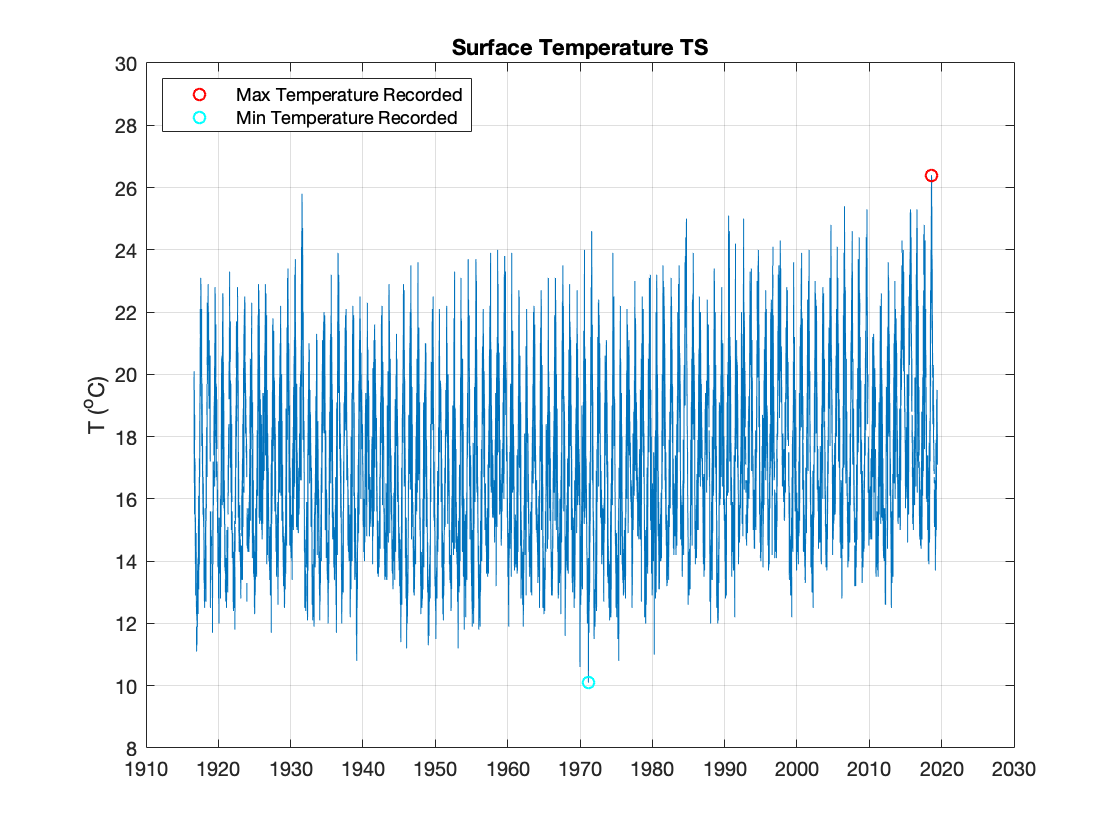

title('Surface Temperature TS');legend({'Max Temperature Recorded','Min Temperature Recorded'},'Location','NW');ylim([8,30])
ylabel('T (^oC)')
datetick

## Problem 3

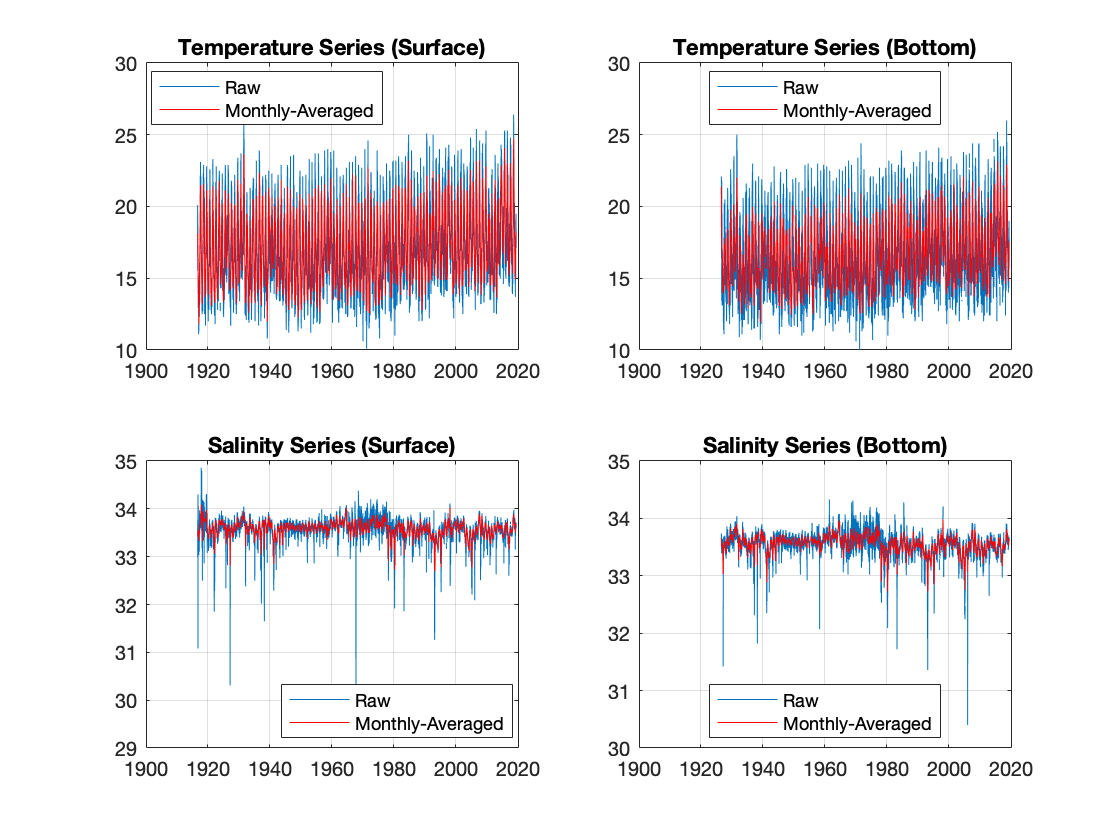

% plot the monthly averaged time series for each variable

clc;clear;clf;close
load('SIO_PIER_1916_201905.mat');
% [mean_t, mean_var] = monthly_avg(time,var,N);
var = ["Ts";"Tb";"Ss";"Sb"];
for i=1:4
    subplot(2,2,i);
    eval(['[mean_t, mean_var] = monthly_avg(t,' num2str(var(i)) ',10);']);
    eval(['plot(t,' num2str(var(i)) ');']);hold on
    plot(mean_t,mean_var','r');
    grid;datetick;legend({'Raw','Monthly-Averaged'},'location','best')
    subplot(2,2,1);title('Temperature Series (Surface)')
    subplot(2,2,2);title('Temperature Series (Bottom)')
    subplot(2,2,3);title('Salinity Series (Surface)')
    subplot(2,2,4);title('Salinity Series (Bottom)')
end

[mean_t1, mean_Ts] = monthly_avg(t,Ts,10); % different data points on each bot/surf arrays
[mean_t2, mean_Tb] = monthly_avg(t,Tb,10);
[mean_t1, mean_Ss] = monthly_avg(t,Ss,10);
[mean_t2, mean_Sb] = monthly_avg(t,Sb,10);

## Problem 4

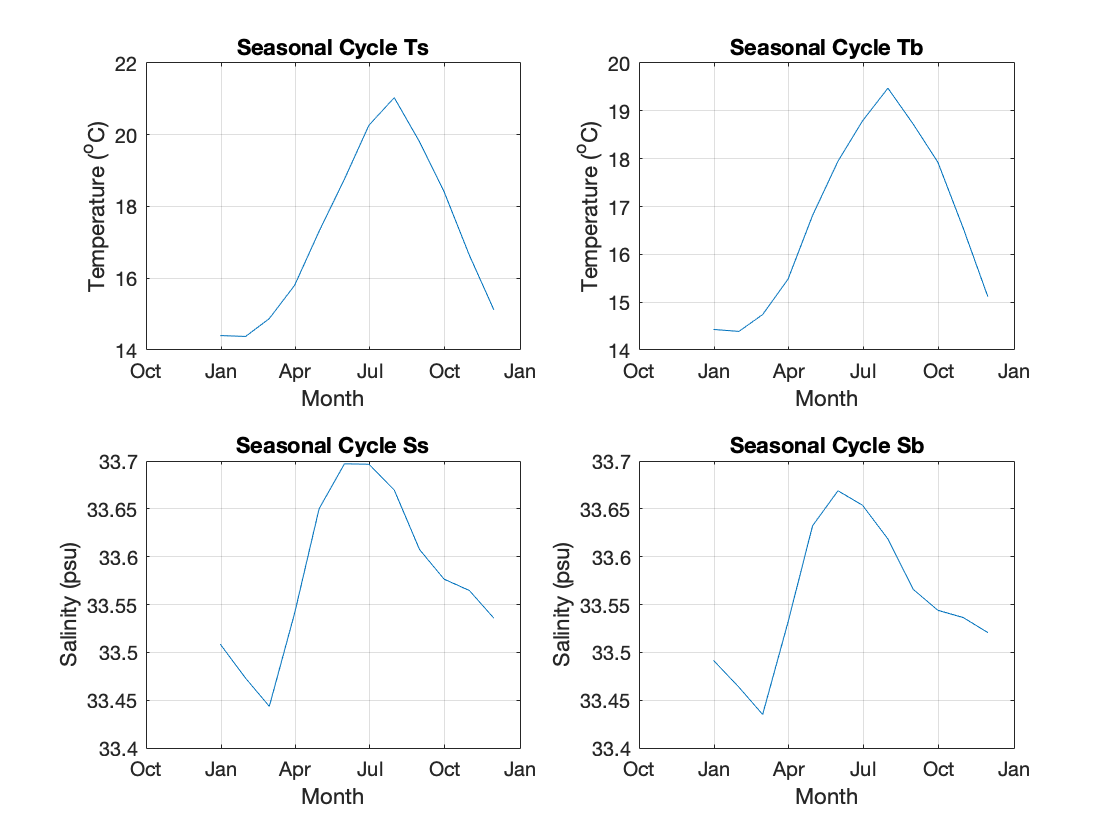

% Compute the seasonal cycle for each variable (the means over all years of
% each month)
clf;close;
x = [datetime(2020,1,0):calmonths(1):datetime(2020,12,0)];
var = ["Ts";"Tb";"Ss";"Sb"];
tmp = datetime(mean_t,'ConvertFrom','datenum');
for i=1:4 % each var
    if i==1 | i==3;tmp = datetime(mean_t1,'ConvertFrom','datenum');end
    if i==2 | i==4; tmp = datetime(mean_t2,'ConvertFrom','datenum');end
    for j=1:12 % months
        g = find(month(tmp)==j);
        eval(['sc(j,i) = nanmean(mean_' num2str(var(i)) '(g));']);
    end
    subplot(2,2,i);plot(x,sc(:,i));grid;xlabel('Month');
    datetick('x','mmm')
    % get correct xlimits 
end
for i=1:2;subplot(2,2,i);ylabel('Temperature (^oC)');end
for i=3:4;subplot(2,2,i);ylabel('Salinity (psu)');end
subplot(2,2,1);title('Seasonal Cycle Ts');
subplot(2,2,2);title('Seasonal Cycle Tb');
subplot(2,2,3);title('Seasonal Cycle Ss');
subplot(2,2,4);title('Seasonal Cycle Sb')

## Problem 5

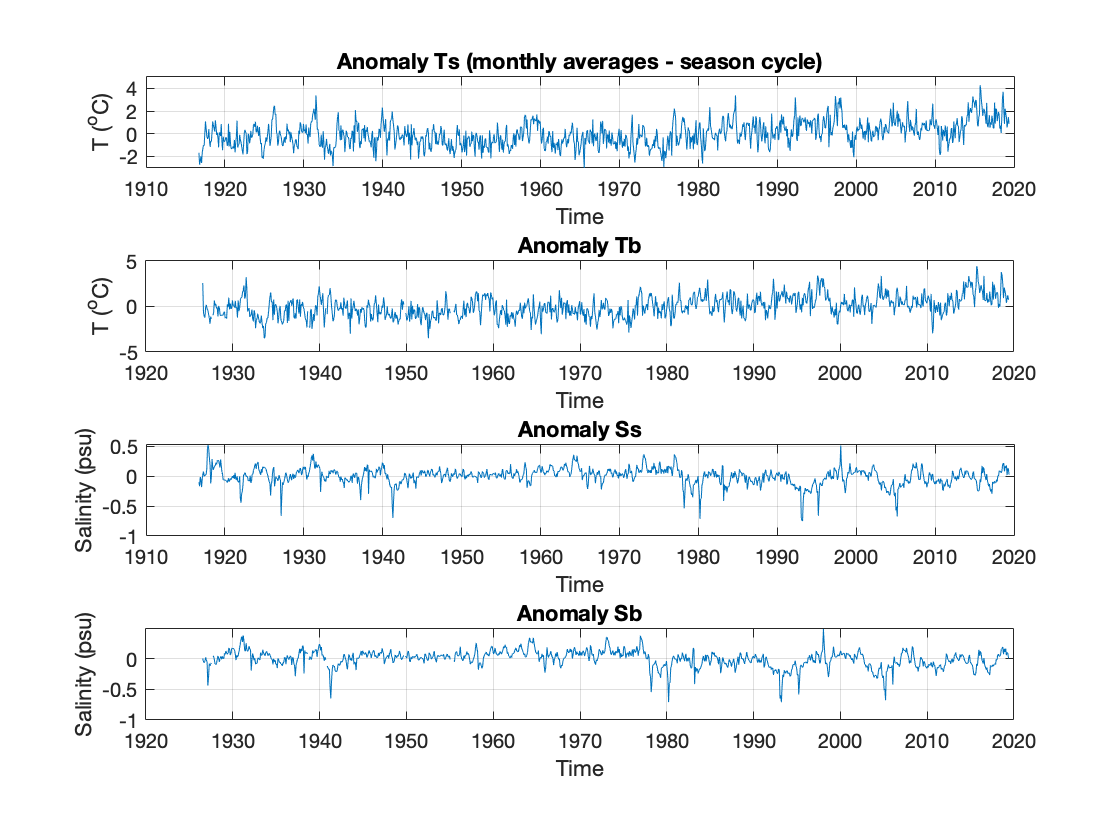

% Compute and plot the anomaly for each variable by removing the 
% seasonal cycle from the monthly time series.

clf
months1 = month(datetime(mean_t1,'ConvertFrom','datenum'));
months2 = month(datetime(mean_t2,'ConvertFrom','datenum'));
% assign new anomaly variables
anom_Ts = NaN(numel(mean_Ts),1);
anom_Ss = NaN(numel(mean_Ts),1);
anom_Tb = NaN(numel(mean_Tb),1);
anom_Sb = NaN(numel(mean_Tb),1);
% I stored the season cycle in columns of sc (weird)
% var = ["Ts";"Tb";"Ss";"Sb"];
for i=1:12
    g = find(months1==i); % gives indices for each month looking at
    anom_Ts(g) = mean_Ts(g)-sc(i,1); % sc(:,1) the seasonal cycle of Ts for each month
    anom_Ss(g) = mean_Ss(g)-sc(i,3);
    g = find(months2==i);
    anom_Tb(g) = mean_Tb(g)-sc(i,2);
    anom_Sb(g) = mean_Sb(g)-sc(i,4);
end
% 
subplot(4,1,1);plot(mean_t1,anom_Ts);datetick;grid;title('Anomaly Ts (monthly averages - season cycle)');xlabel('Time');ylabel('T (^oC)')
subplot(4,1,2);plot(mean_t2,anom_Tb);datetick;grid;title('Anomaly Tb');xlabel('Time');ylabel('T (^oC)')
subplot(4,1,3);plot(mean_t1,anom_Ss);datetick;grid;title('Anomaly Ss');xlabel('Time');ylabel('Salinity (psu)')
subplot(4,1,4);plot(mean_t2,anom_Sb);datetick;grid;title('Anomaly Sb');xlabel('Time');ylabel('Salinity (psu)')

clearvars months1 months2 Tb Ss Sb Sc i j g Readme

## Problem 6

% How are these variables distributed? Plot histograms (normalized to a PDF) of the Ts and Ss anomaly time series. 
% Compare to a Gaussian distribution by overplotting a Gaussian PDF using the sample mean [mean(anom_Ts)] 
% [std(anom_Ts)] and standard deviation of each time series.
clf;
subplot(1,2,1)
x=linspace(-4,4,100);
histogram(anom_Ts,100,'Normalization','pdf')
y = normpdf(x,mean(anom_Ts),std(anom_Ts));hold;plot(x,y,'linewidth',2);grid

Current plot held


title('Ts Histogram normalized to PDF');legend({'Ts Hist','Gaussian distribution'})
subplot(1,2,2)
x=linspace(-0.8,0.8,100);
histogram(anom_Ss,100,'Normalization','pdf')
y = normpdf(x,mean(anom_Ss),std(anom_Ss));hold;plot(x,y,'linewidth',2);grid

Current plot held


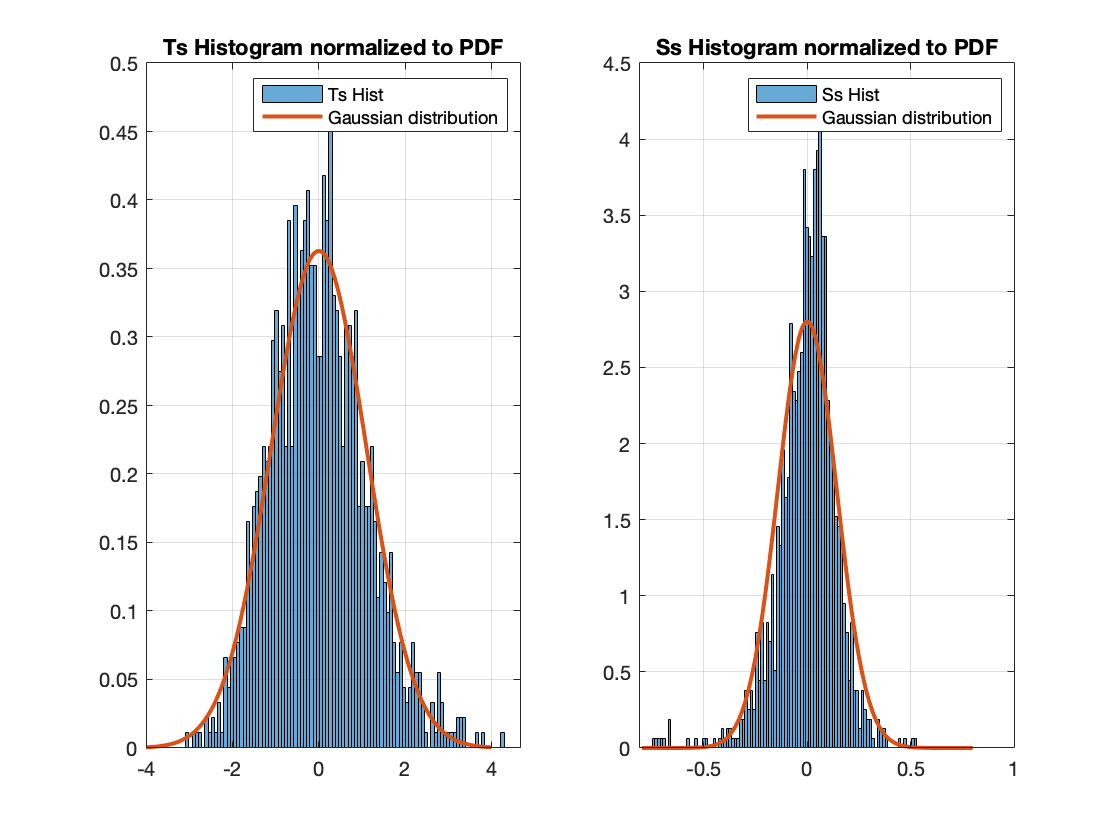

title('Ss Histogram normalized to PDF');legend({'Ss Hist','Gaussian distribution'})

It looks like these variables are pretty much already normally distributed as they almost fit the overlaid gaussian distribution.

## Problem 7

% Can you see evidence of long-term change using histograms? Compare histograms
% (normalized to a PDF) of the Ts and Ss anomaly time series for the first 20 years of
% the record compared to the last 20 years.
clf
% create subset
years1 = year(datetime(mean_t1,'ConvertFrom','datenum'));
g = find(years1<=1936);
% plot
subplot(2,2,1);histogram(anom_Ts(g),'Normalization','pdf');grid;xlabel('T (^oC)');ylabel('Probability (%)');title('Ts Histogram (1916-1936)')
subplot(2,2,2);histogram(anom_Ss(g),'Normalization','pdf');grid;xlabel('S (psu)');ylabel('Probability (%)');title('Ss Histogram (1916-1936)')
g = (years1>=2000); disp(sum(g)); %-- pretty much same amount of data

   233



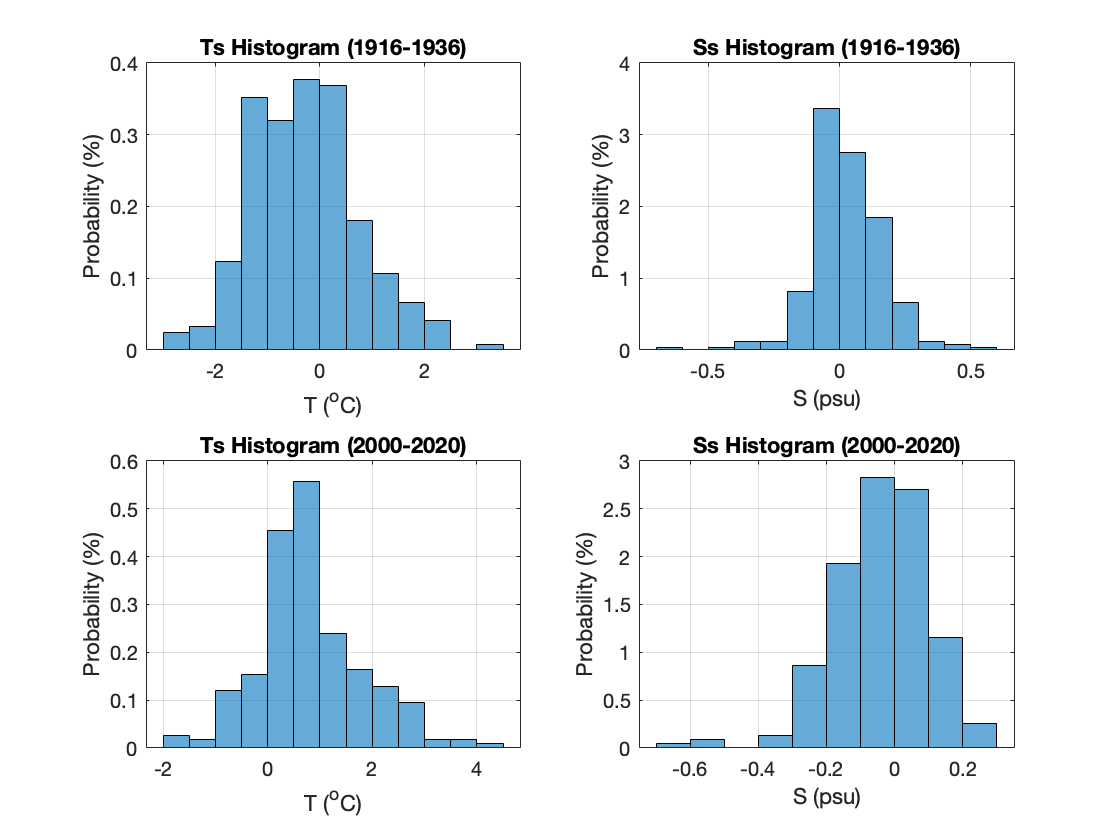

% create subset of data for last 20 years
g = find(years1>=2000);
% plot last 20 years
subplot(2,2,3);histogram(anom_Ts(g),'Normalization','pdf');grid;xlabel('T (^oC)');ylabel('Probability (%)');title('Ts Histogram (2000-2020)')
subplot(2,2,4);histogram(anom_Ss(g),'Normalization','pdf');grid;xlabel('S (psu)');ylabel('Probability (%)');title('Ss Histogram (2000-2020)')

Yes, it seems as the temperature and salinity both become more spread out from 1916-1936 to the last 20 years. For the first 20 years of the Ss data there is an erroneous value I feel like at ~31 psu, otherwise the Ss spreads out in distribution from the first 20 years to the last 20.

## Problem 8

% To emphasize how things have changed, let's estimate an exceedance probability.
% Assuming a Gaussian distribution, what is the probability that the max monthly Ts in
% the first 20 years of the record is exceeded in the last 20 years of the record?
% do the CDF of the dataset (last 20 years) exceeds max value of first 20
% yrs
clf
tmp = year(datetime(mean_t1,'ConvertFrom','datenum'));
g = find(tmp<=1936);
max_Ts = max(mean_Ts(g));
g = find(tmp>=2000);

prob = 1-normcdf(max_Ts,nanmean(mean_Ts(g)),nanstd(mean_Ts(g)))

prob = 0.0144

x=linspace(min(mean_Ts(g)),max(mean_Ts(g)),100);
% plot(x,normcdf(x,mean(e),std(e)),'LineWidth',2)
plot(x,normcdf(x,nanmean(mean_Ts(g)),nanstd(mean_Ts(g))));grid;hold;scatter(max_Ts,abs(1-prob))

Current plot held


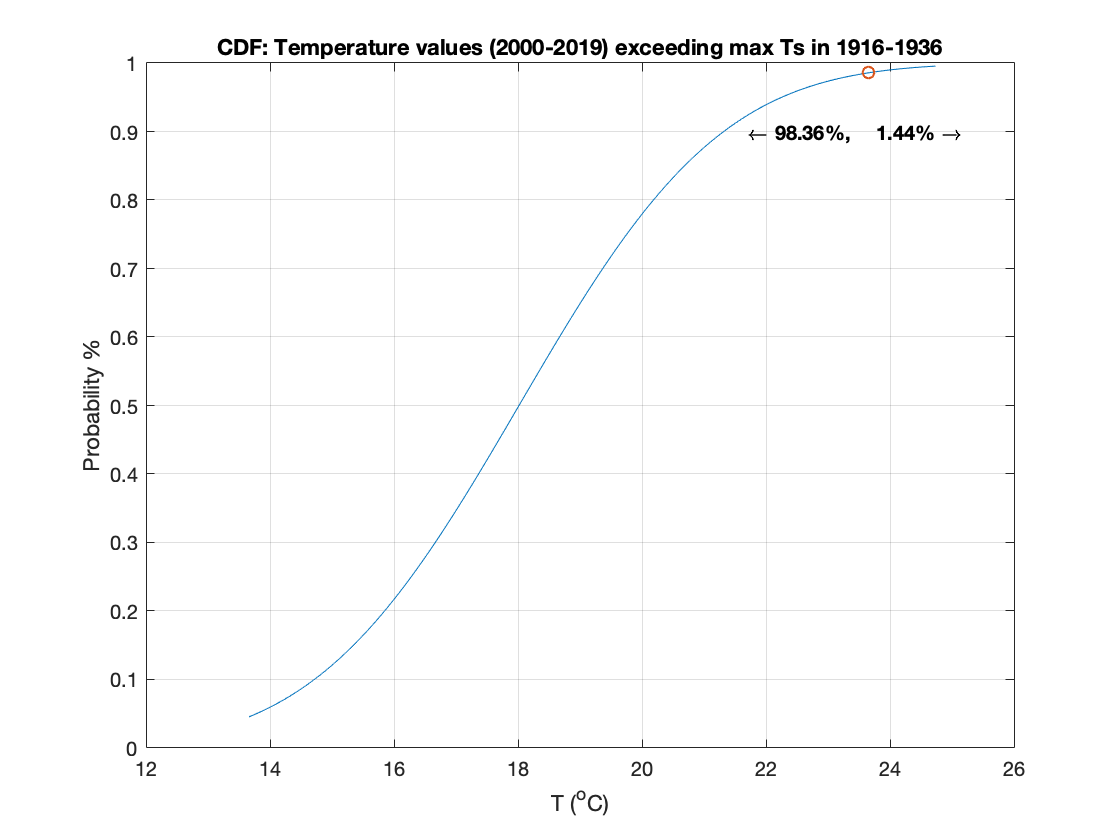

ylabel('Probability %');xlabel('T (^oC)');title('CDF: Temperature values (2000-2019) exceeding max Ts in 1916-1936')
text(21.6,0.9, '\bf \leftarrow 98.36%,')
text(23.6,0.9, '\bf  1.44% \rightarrow')

% clearvars -except mean_t1 mean_t2 anom_Ts anom_Tb anom_Ss anom_Sb 


**The probability of the Ts dataset of the last 20 years exceeding the maximum Ts of the first 20 years is 22.1%.** We do this by doing the 1-cdfplot(max_Ts_ss, [Ts data from last 20 years]); if we do normcdf(value,...) only it will calculate the probability of the dataset being less than or equal to our max_Ts_ss. So we do 1-cdfplot(...) to get the probability that our data will be greater than this value.

## Problem 9

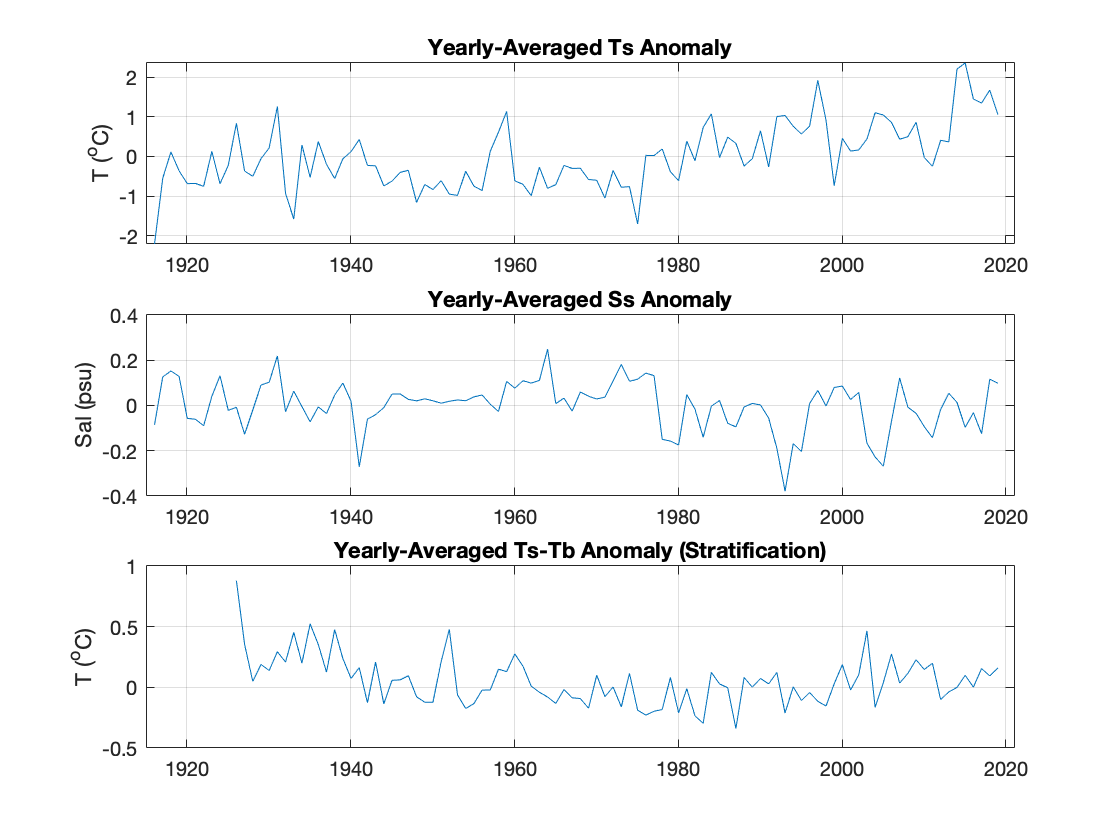

% Compute year-averaged time series from the monthly Ts
% and Ss anomalies, as well as Ts-Tb (a rough measure of stratification).
clf
years1 = year(datetime(mean_t1,'convertfrom','datenum'));
years = unique(years1);
x = [datetime(1916,1,15):calyears(1):datetime(2019,1,15)];
% define arrays
ya_Ts_anom = NaN(years(end)-years(1),1);
ya_Ss_anom = NaN(years(end)-years(1),1);
jj=1; % counter
for i=years(1):years(end)
    g = find(years1==i);
    ya_Ts_anom(jj,1) = nanmean(anom_Ts(g));
    ya_Ss_anom(jj,1) = nanmean(anom_Ss(g));
    jj=jj+1;
end
subplot(3,1,1);plot(x,ya_Ts_anom);title('Yearly-Averaged Ts Anomaly');ylabel('T (^oC)')
subplot(3,1,2);plot(x,ya_Ss_anom);title('Yearly-Averaged Ss Anomaly');ylabel('Sal (psu)')
% get ya_Tb|Sb_anom
years2 = year(datetime(mean_t2,'convertfrom','datenum'));
years = unique(years2);
x = [datetime(years(1),1,15):calyears(1):datetime(years(end),1,15)];
% define arrays
ya_Tb_anom = NaN(years(end)-years(1),1);
ya_Sb_anom = NaN(years(end)-years(1),1);

jj=1; % counter
for i=years(1):years(end)
    g = find(years2==i);
    ya_Tb_anom(jj,1) = nanmean(anom_Tb(g)); % ya = yearly-averaged
    ya_Sb_anom(jj,1) = nanmean(anom_Sb(g));
    jj=jj+1;
end
% make ya_Tb_anom same size as ya_Ts_anom
if numel(ya_Ts_anom)~=numel(ya_Tb_anom)
    tmp = size(ya_Ts_anom,1)-size(ya_Tb_anom,1);
    ya_Tb_anom = [NaN(tmp,1); ya_Tb_anom];
end
% reset x vector from 1916-2019
x = [datetime(1916,1,15):calyears(1):datetime(2019,1,15)];

subplot(3,1,3);plot(x,ya_Ts_anom-ya_Tb_anom);ylabel('T (^oC)')
title('Yearly-Averaged Ts-Tb Anomaly (Stratification)')
for i=1:3;
    subplot(3,1,i);
    xlim([datetime(1915,1,0),datetime(2021,1,0)]);grid
end

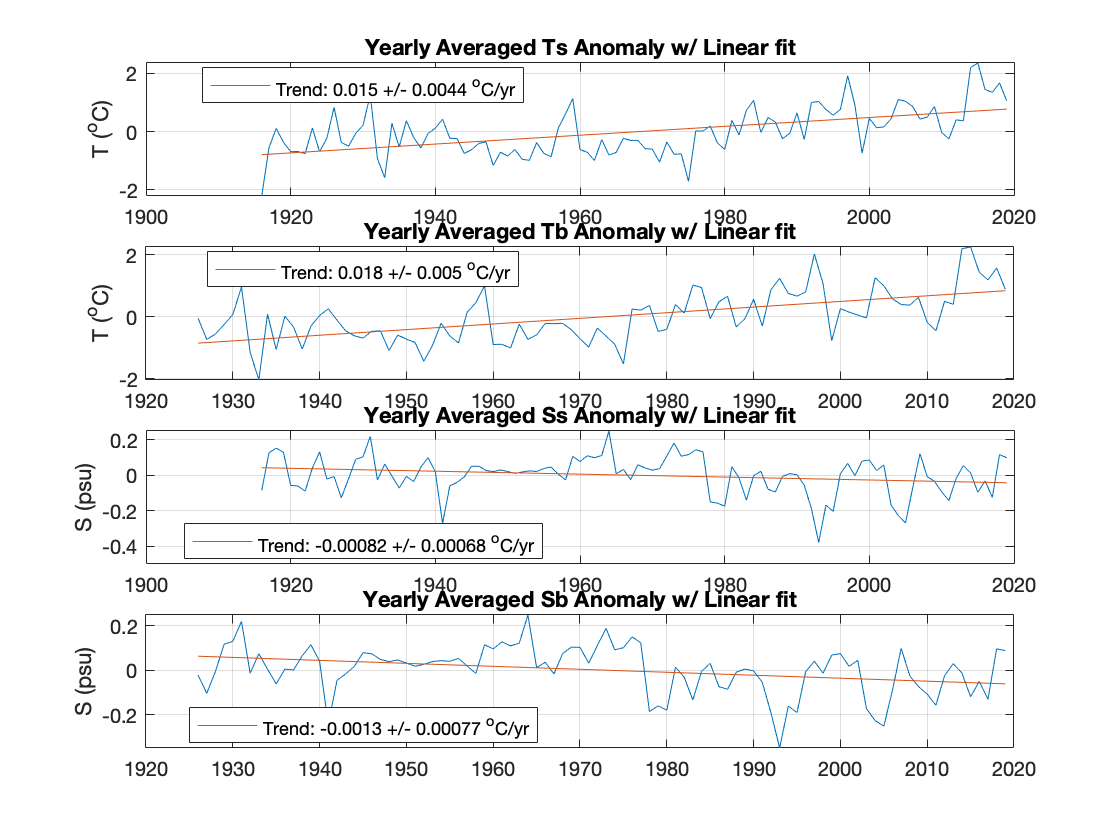


% Compute the linear trends for each time series and give the 95% confidence
% interval.  Assume that each year represents an independent data point. 
% Which trends are significantly different than zero?
clf
% Function syntax: trendd(time_array,ya_var_anom,o)
% Ts trend
subplot(4,1,1);[b1, bint1] = trendd(mean_t1,ya_Ts_anom,1);
% Tb trend
%
ya_Tb_anom = ya_Tb_anom(~isnan(ya_Tb_anom));
subplot(4,1,2);trendd(mean_t,ya_Tb_anom,1);
% Ss trend
subplot(4,1,3);trendd(mean_t1,ya_Ss_anom,1);
% Sb trend
subplot(4,1,4);trendd(mean_t2,ya_Sb_anom,1);
for i=1:4;subplot(4,1,i)
    grid;
    a = strcat('Yearly Averaged',{' '},var(i),{' '},'Anomaly w/ Linear fit');
    title(a);
end
for i=1:2;subplot(4,1,i);ylabel('T (^oC)');end
for i=3:4;subplot(4,1,i);ylabel('S (psu)');end

The temperature trends for both surface and bottom are both significantly different from zero and somewhat with the bottom salinity as well. The surface salinity remains close to 0 for the trend. A trend is significant when the variability is greater than the slope itself I think

## Problem 10

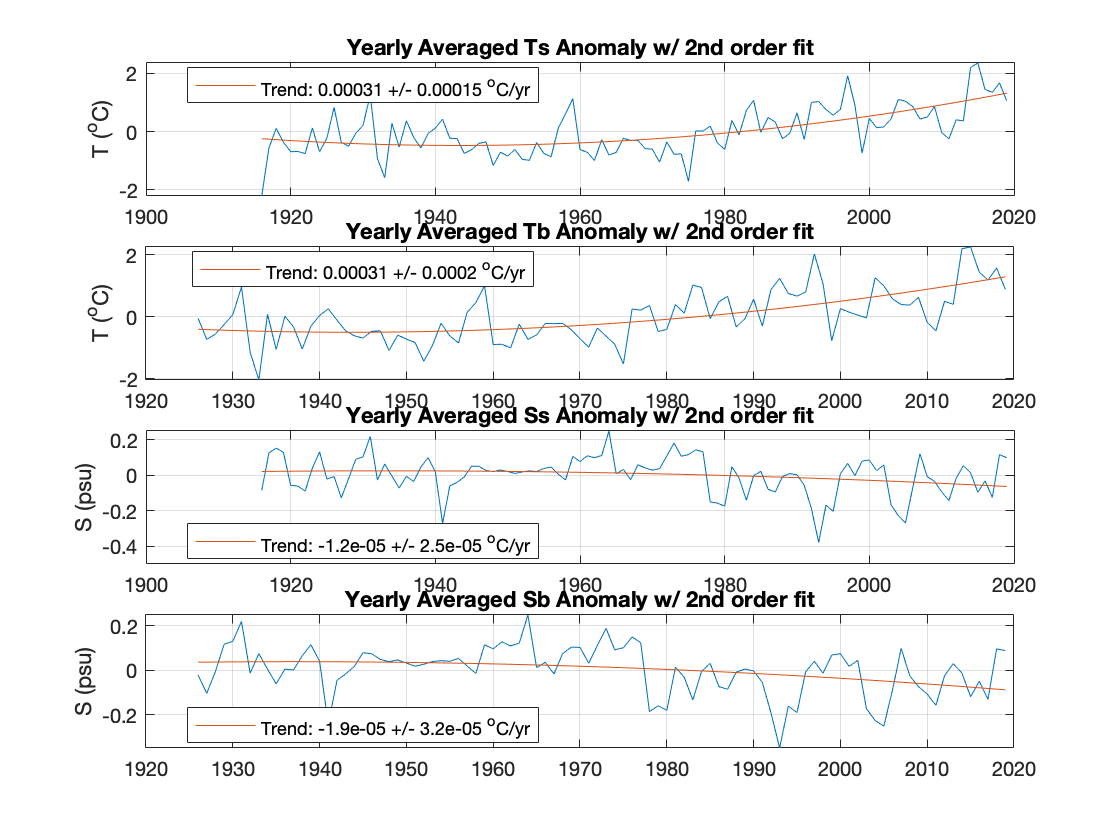

% Compute a 2nd-order polynomial to each time series. Do any of the series exhibit a
% significant acceleration?
clf
% Function syntax: trendd(time_array,ya_var_anom,o)
% Ts trend
subplot(4,1,1);[b2, bint2] = trendd(mean_t1,ya_Ts_anom,2);
% Tb trend
subplot(4,1,2);trendd(mean_t2,ya_Tb_anom,2);
% Ss trend
subplot(4,1,3);trendd(mean_t1,ya_Ss_anom,2);
% Sb trend
subplot(4,1,4);trendd(mean_t2,ya_Sb_anom,2);
for i=1:4;subplot(4,1,i)
    grid;
    a = strcat('Yearly Averaged',{' '},var(i),{' '},'Anomaly w/ 2nd order fit');
    title(a);
end
for i=1:2;subplot(4,1,i);ylabel('T (^oC)');end
for i=3:4;subplot(4,1,i);ylabel('S (psu)');end

All seem to exhibit some acceleration except for surface salinity. It makes sense that the temperatures would increase though I feel like salinity should increase in trend as well. However these trends are correct and the decrease in salinity trend could be to increased upwelling (maybe due to increased westerly winds due to larger pressure gradient? -- speculating) over time and more fresh water perhaps. 

## Problem 11

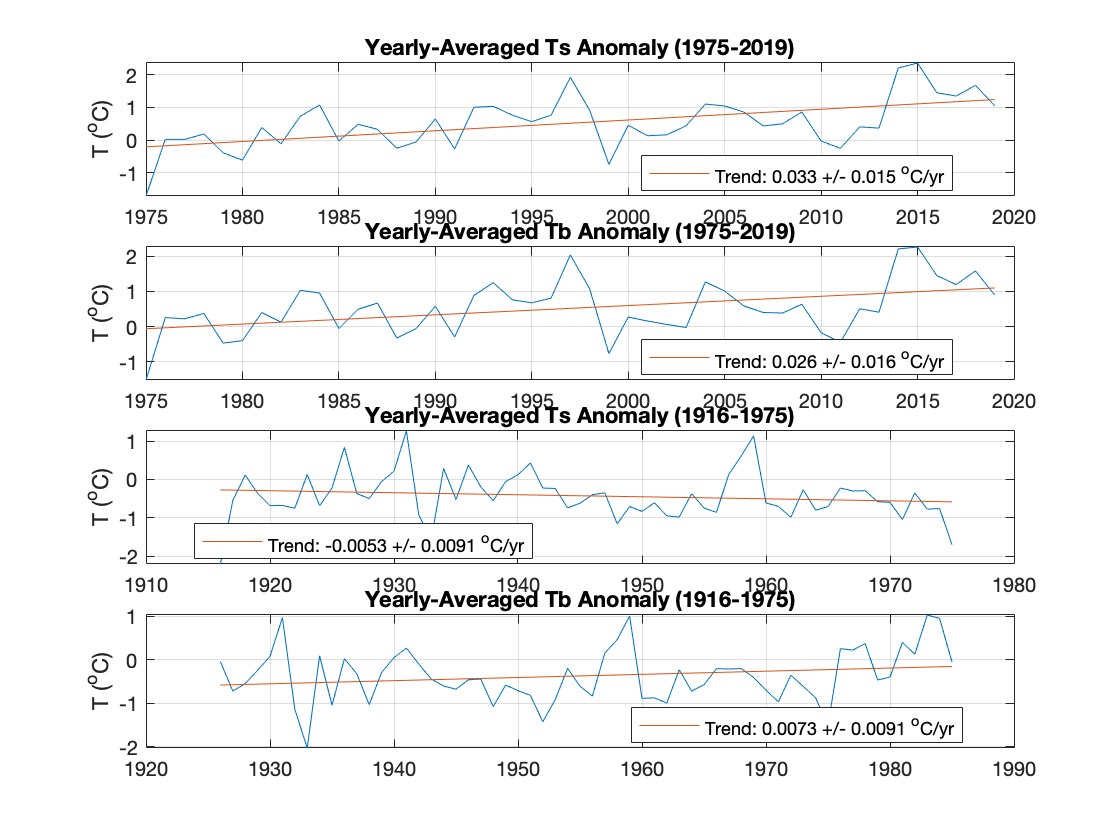

% There appears to be a noticeable uptick in temperature since the mid 1970s. Compute
% the linear trend and 95% confidence of each series since 1975. How does the post-
% 1970s trend compare to the pre-1970s trend?
clf

% trends 1975-2019
years1 = datetime(mean_t1,'ConvertFrom','datenum');
years2 = datetime(mean_t2,'ConvertFrom','datenum');
g = year(years1)>=1975;
f = unique(year(years1))>=1975;
subplot(4,1,1);[b3, bint3] = trendd(mean_t1(g),ya_Ts_anom(f),1);title('Yearly-Averaged Ts Anomaly (1975-2019)')
h = year(years2)>=1975;
k = unique(year(years2))>=1975;
subplot(4,1,2);trendd(mean_t2(h),ya_Tb_anom(k),1);title('Yearly-Averaged Tb Anomaly (1975-2019)')

% trends 1916-1975
g = year(years1)<=1975;
f = unique(year(years1))<=1975;
subplot(4,1,3);trendd(mean_t1(g),ya_Ts_anom(f),1);title('Yearly-Averaged Ts Anomaly (1916-1975)')
h = year(years2)<=1975;
k = unique(year(years2))<=1975;
subplot(4,1,4);trendd(mean_t2(g),ya_Tb_anom(f),1);title('Yearly-Averaged Tb Anomaly (1916-1975)')
for i=1:4;subplot(4,1,i);ylabel('T (^oC)');grid;end

clearvars a f g h t i j jj k max_Ts mean_Sb mean_Ss mean_Tb prob tmp x y Readme

The post 1970s trend is definitely rapidly increasing (positive) while we see the pre-1970s trend is negative or in Tb case slightly positive.

## Problem 12

Extrapolate Ts to 2100 using the linear fit over the entire record, the 2nd order fit, and the linear fit since 1975. Plot each of these estimates on a single time series along with the monthly-averaged anomaly. Comment on these results. When would these projections start to diverge?

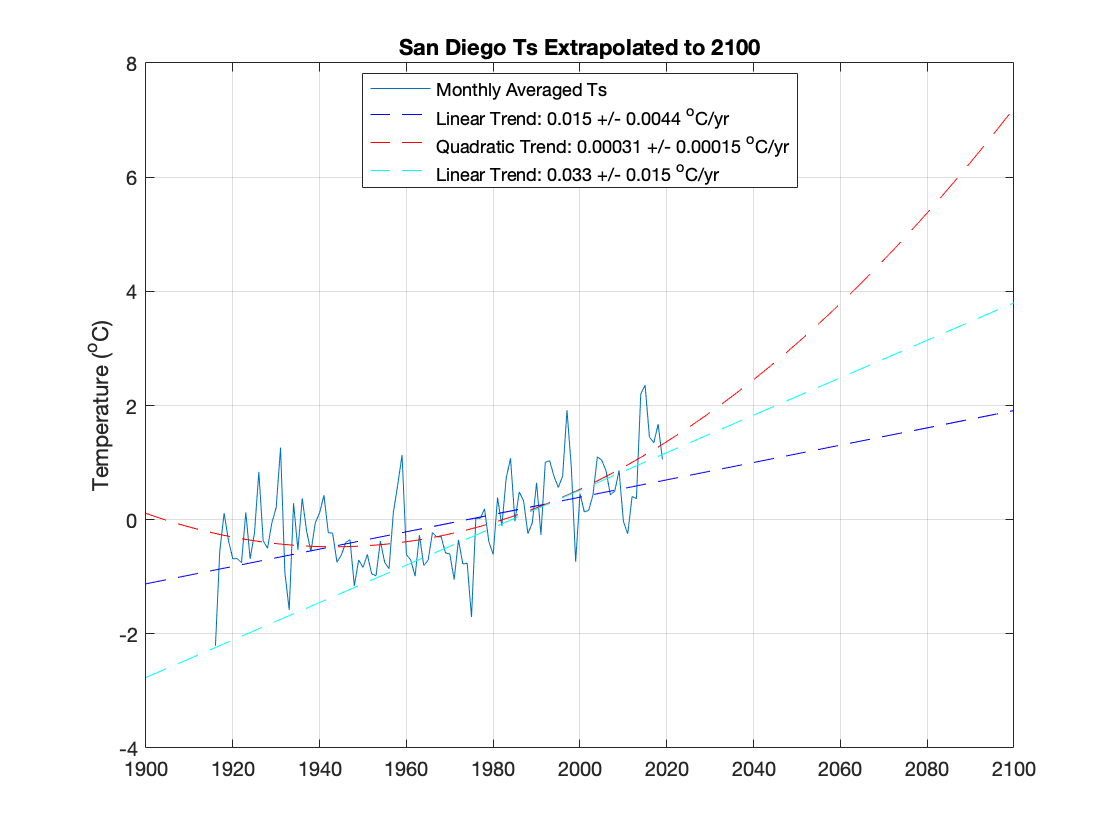

clf
% plot the orig monthly averaged Ts and get the extrapolation cofficients
years = unique(year(datetime(mean_t1,'convertfrom','datenum')));
yrs = [1900:2100]';
x0 = yrs-nanmean(years);
x1 = [x0 ones(length(yrs),1)];
x2 = [x0.^2 x0 ones(length(yrs),1)];
plot(years,ya_Ts_anom);hold on

% plot the extrapolation to 2100 for 1st and 2nd orders
x1 = [yrs-nanmean(yrs) ones(length(yrs),1)];  
% adjust intercepts for b1 (linear not matching up
m=x1*b1;
adj = m(yrs==1975)-0.0152;
plot(yrs,x1*b1-adj,'b--') % b isthe value from privous problem
plot(yrs,x2*b2, 'r--')
% plot linear fit since 1975
yrs = (1900:2100)';
x0 = yrs-nanmean(yrs);
x3 = [x0 ones(length(yrs),1)];
plot(yrs,x3*b3,'c--')
grid;ylabel('Temperature (^oC)');title('San Diego Ts Extrapolated to 2100')
xlim([1900,2100])
ci1 = (bint1(1,2)-bint1(1,1))/2;
ci2 = (bint2(1,2)-bint2(1,1))/2;
ci3 = (bint3(1,2)-bint3(1,1))/2;
a1 = ['Linear Trend: ',num2str(b1(1),2),' +/- ',num2str(ci1,2),' ^oC/yr'];
a2 = ['Quadratic Trend: ',num2str(b2(1),2),' +/- ',num2str(ci2,2),' ^oC/yr'];
a3 = ['Linear Trend: ',num2str(b3(1),2),' +/- ',num2str(ci3,2),' ^oC/yr'];
legend({'Monthly Averaged Ts', a1,a2,a3},'location','best')

% I just realized that my trendd.m script will label the Salinity trends
% with ^oC/yr when it should be in psu/yr.